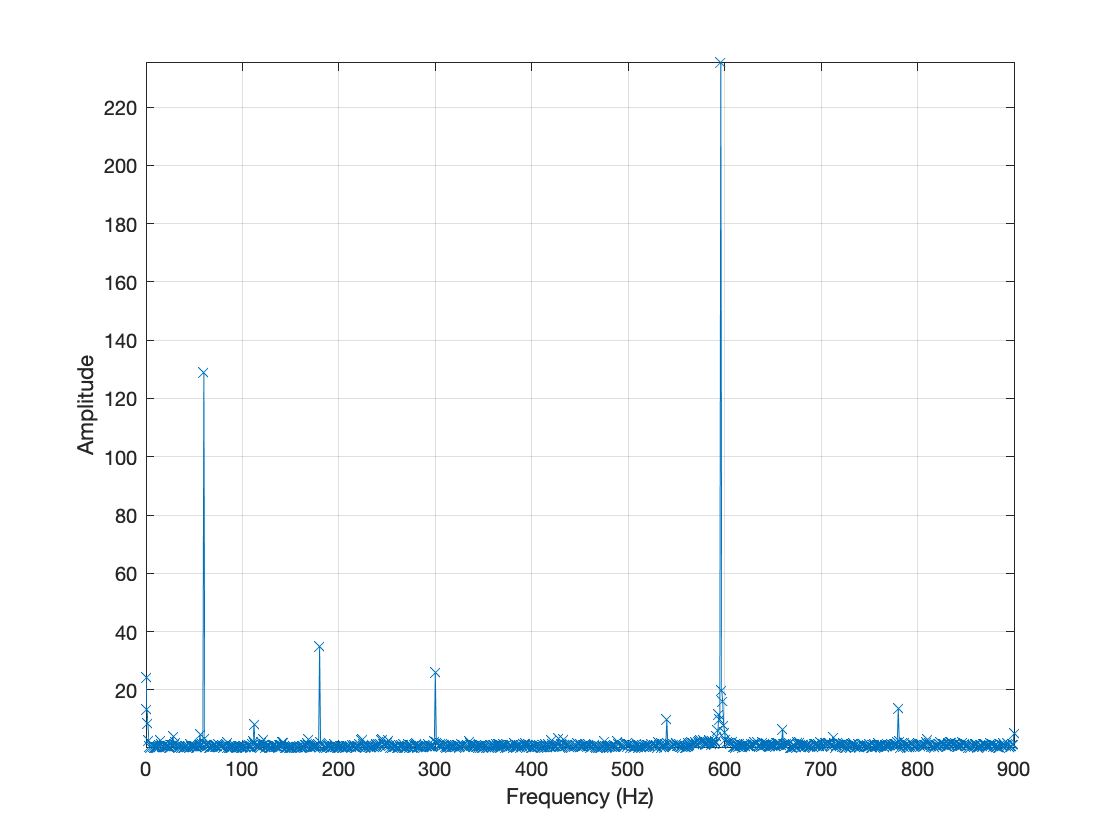

Fs = 40000;

sigLen = numel(dat);
fchirp = fft(dat);
fr = Fs*(0:1/Fs:1-1/Fs);
plot(fr(1:sigLen/2),abs(fchirp(1:sigLen/2)),'x-')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
axis tight
grid on
xlim([0 900])

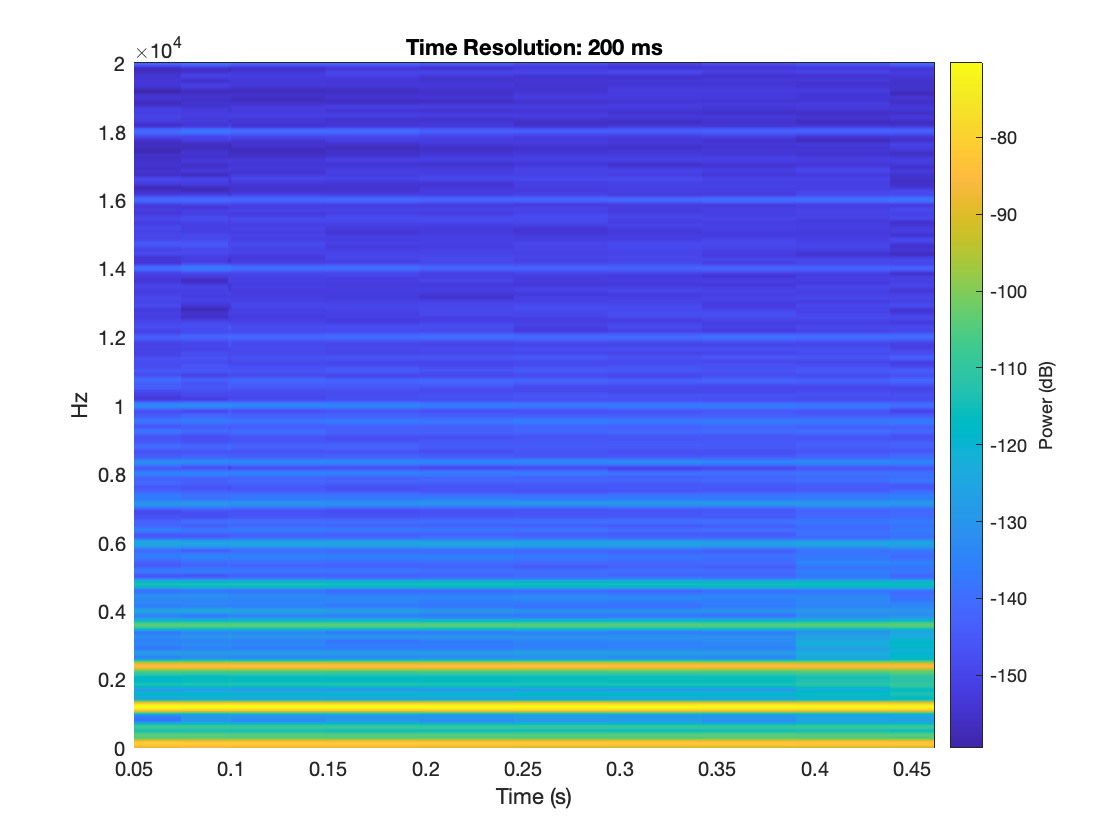

Index exceeds the number of array elements (20000).

Error in untitled>helperPlotSpectrogram (line 35)
plot(t(idxbegin:idxend1),(instfreq1(idxbegin:idxend1)),'k--');

helperPlotSpectrogram(dat, tim, Fs, 200);

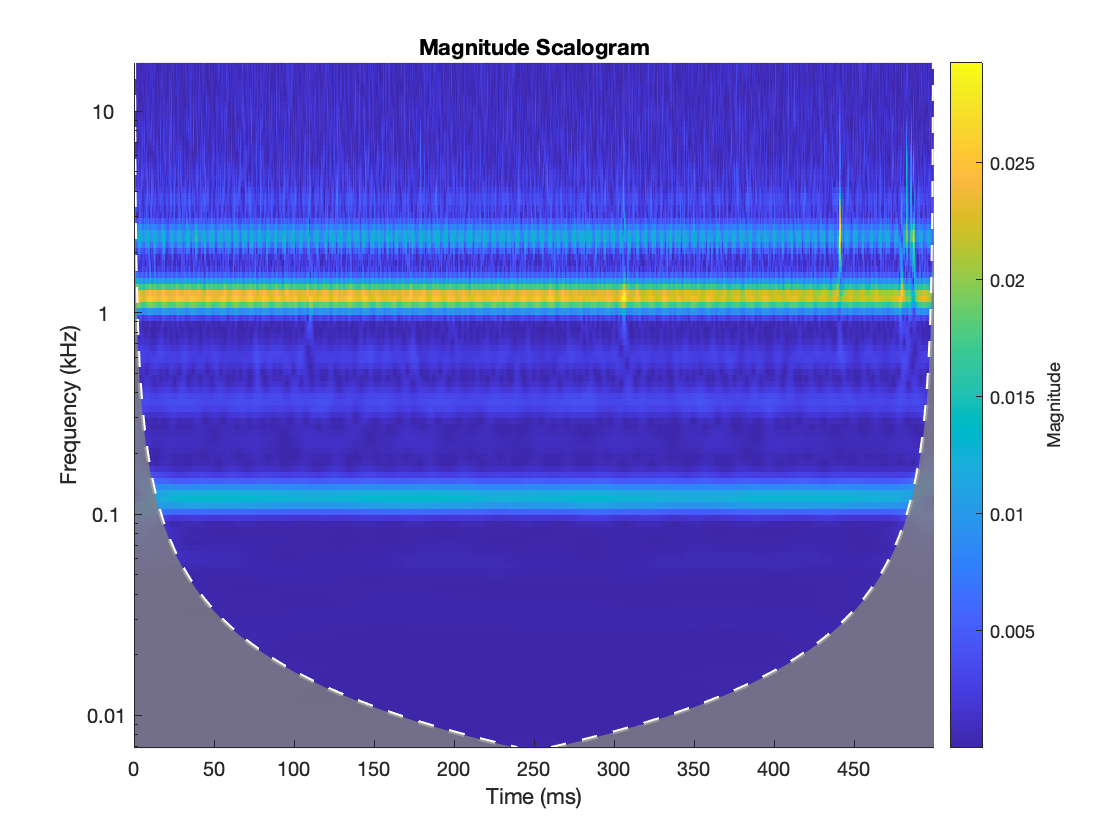

cwt(dat, Fs);

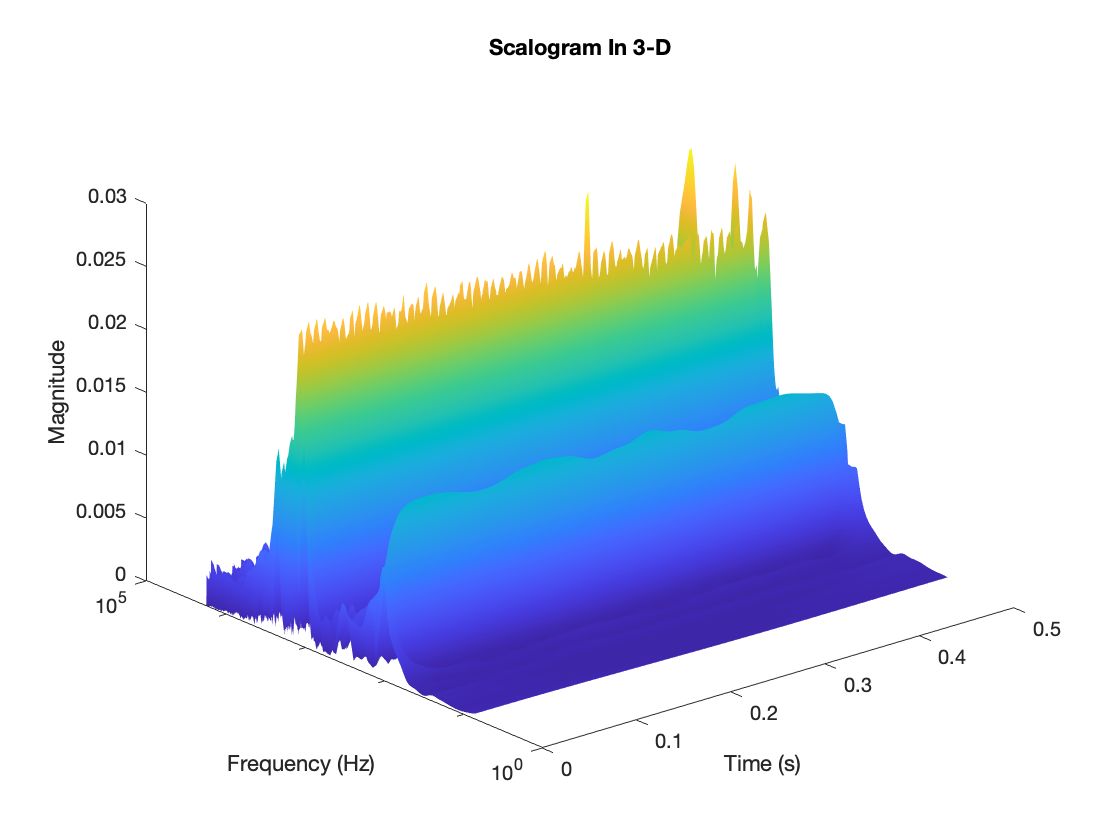

helperPlotScalogram3d(dat, Fs);

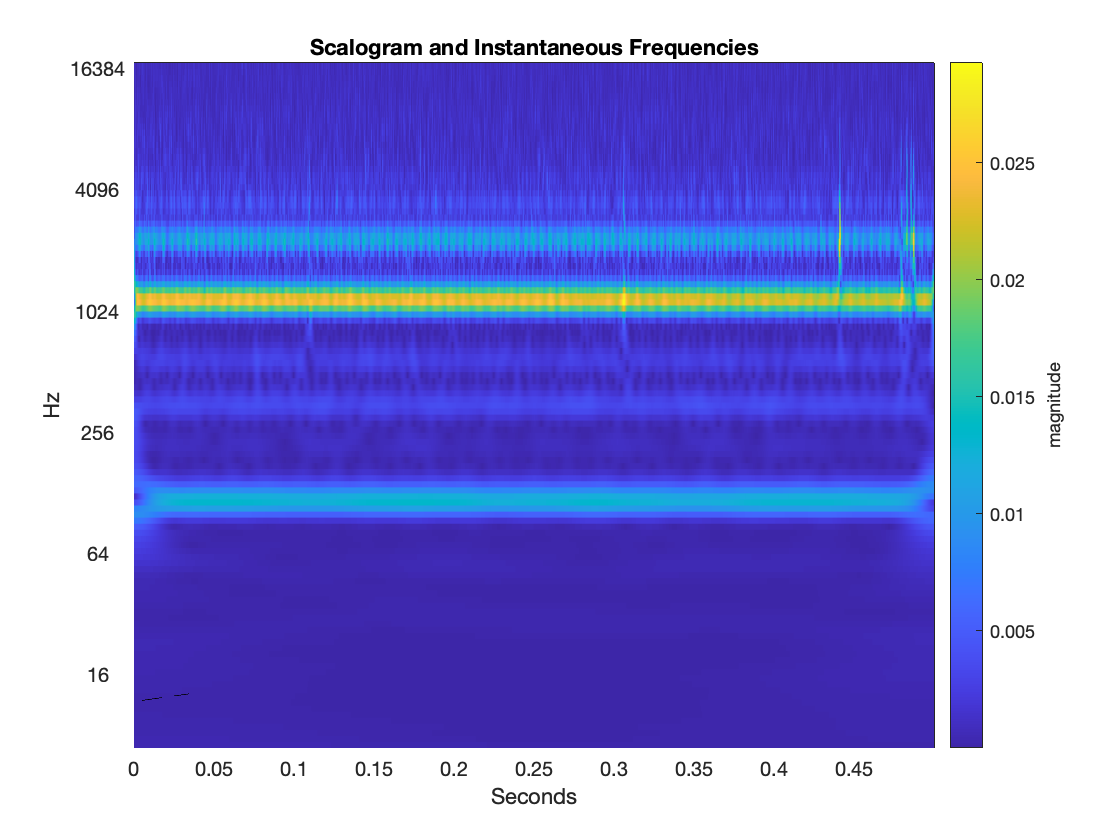

helperPlotScalogram(dat, Fs);

function helperPlotSpectrogram(sig,t,Fs,timeres)
% This function is only intended to support this wavelet example.
% It may change or be removed in a future release.

[px,fx,tx] = pspectrum(sig,Fs,'spectrogram','TimeResolution',timeres/1000);
hp = pcolor(tx,fx,20*log10(abs(px)));
hp.EdgeAlpha = 0;
ylims = hp.Parent.YLim;
yticks = hp.Parent.YTick;
cl = colorbar;
cl.Label.String = 'Power (dB)';
axis tight
hold on
title(['Time Resolution: ',num2str(timeres),' ms'])
xlabel('Time (s)')
ylabel('Hz');
dt  = 1/Fs;
idxbegin = round(0.1/dt);
idxend1 = round(0.68/dt);
idxend2 = round(0.75/dt);
instfreq1 = abs((15*pi)./(0.8-t).^2)./(2*pi);
instfreq2 = abs((5*pi)./(0.8-t).^2)./(2*pi);
plot(t(idxbegin:idxend1),(instfreq1(idxbegin:idxend1)),'k--');
hold on;
plot(t(idxbegin:idxend2),(instfreq2(idxbegin:idxend2)),'k--');
ylim(ylims);
hp.Parent.YTick = yticks;
hp.Parent.YTickLabels = yticks;
hold off
end

function helperPlotScalogram(sig,Fs)
% This function is only intended to support this wavelet example.
% It may change or be removed in a future release.
[cfs,f] = cwt(sig,Fs);

sigLen = numel(sig);
t = (0:sigLen-1)/Fs;

hp = pcolor(t,log2(f),abs(cfs));
hp.EdgeAlpha = 0;
ylims = hp.Parent.YLim;
yticks = hp.Parent.YTick;
cl = colorbar;
cl.Label.String = 'magnitude';
axis tight
hold on
title('Scalogram and Instantaneous Frequencies')
xlabel('Seconds');
ylabel('Hz');
dt  = 1/2048;
idxbegin = round(0.1/dt);
idxend1 = round(0.68/dt);
idxend2 = round(0.75/dt);
instfreq1 = abs((15*pi)./(0.8-t).^2)./(2*pi);
instfreq2 = abs((5*pi)./(0.8-t).^2)./(2*pi);
plot(t(idxbegin:idxend1),log2(instfreq1(idxbegin:idxend1)),'k--');
hold on;
plot(t(idxbegin:idxend2),log2(instfreq2(idxbegin:idxend2)),'k--');
ylim(ylims);
hp.Parent.YTick = yticks;
hp.Parent.YTickLabels = 2.^yticks;
end

function helperPlotScalogram3d(sig,Fs)
% This function is only intended to support this wavelet example.
% It may change or be removed in a future release.
figure
[cfs,f] = cwt(sig,Fs);

sigLen = numel(sig);
t = (0:sigLen-1)/Fs;
surface(t,f,abs(cfs));
xlabel('Time (s)')
ylabel('Frequency (Hz)')
zlabel('Magnitude')
title('Scalogram In 3-D')
set(gca,'yscale','log')
shading interp
view([-40 30])
end


